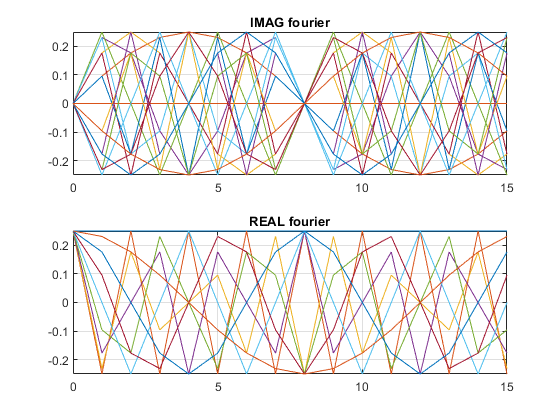

% Zielniski 2.5 Przykad transofrmacji orogonalnych sygnalow

% Transformaty ortogonalne sygnałów
% 1) kształt dyskretnych baz: Fouriera, kosinusowej, sinusowej, Hadamarda, Walsha
% 2) dopasowanie bazy − przykładowa dekompozycja dwóch sygnałów
clear all; subplot(111);
N=16; % wybór liczby (długości) funkcji bazowych (wymiar przestrzeni wektorowej)
n=0:N-1; % indeksy wszystkich próbek poszczególnych funkcji bazowych
NN=2*N; % zmienna pomocnicza

% Kształt funkcji bazowych dla transformacji kosinusowej i sinusowej
% n-ta próbka k-tej funkcji bazowej
f = 1/sqrt(N);  %normalizacja
c = [sqrt(1/N) sqrt(2/N)*ones(1, N-1)];
s = sqrt(2/(N+1));

for k=0:N-1
    baza_fouriera(k+1, n+1) = f * exp(2i*pi*k*n/N); % zamiast kolejnej petli for n:N-1 jest wektor razy skalar wpisny jak wiersz a kolejna baza jako kolejny wiesz
    baza_cos(k+1, n+1) = c(k+1) * cos(k*pi*(n+1/2)/N);
    baza_sin(k+1, n+1) = s * sin(pi*(k+1)*(n+1) / (N+1));
    
end
% Kształt funkcji bazowych dla transformacji Hadamarda
% n-ta próbka k-tej funkcji bazowej
m=log2(N); c = sqrt(1/N);
for k=0:N-1
    kk = k;
    for i=0:m-1
        ki(i+1) = rem(kk, 2); kk=floor(kk/2);
    end
    for n=0:N-1
        nn = n;
        for i=0:m-1
            ni(i+1) = rem(nn, 2); nn = floor(nn/2);
        end
        baza_HD(k+1,n+1) = c * (-1)^sum(ki .* ni);
    end
end

% Kształt funkcji bazowych dla transformacji Haara
% n-ta próbka k-tej funkcji bazowej
c = sqrt(1/N); baza_HR(1,1:N) = c*ones(1, N);
for k = 1:N-1
    p = 0;
    while (k+1 > 2^p)
        p = p + 1;
    end
    p=p-1;
    q=k-2^p+1;
    for n=0:N-1
        x = n/N;
        if ( ((q-1)/2^p <= x) & (x < (q-1/2)/2^p) )
            baza_HR(k+1, n+1) = c*2^(p/2);
        elseif ( ((q-1/2)/2^p <= x) & (x < q/2^p) )
            baza_HR(k+1, n+1) = -c*2^(p/2);
        else baza_HR(k+1, n+1) = 0;
        end
    end
end
n=0:N-1;
figure()
subplot(2,1,1); plot(n, imag(baza_fouriera(:,:))); grid; title('IMAG fourier');
subplot(2,1,2); plot(n, real(baza_fouriera(:,:))); grid; title('REAL fourier');

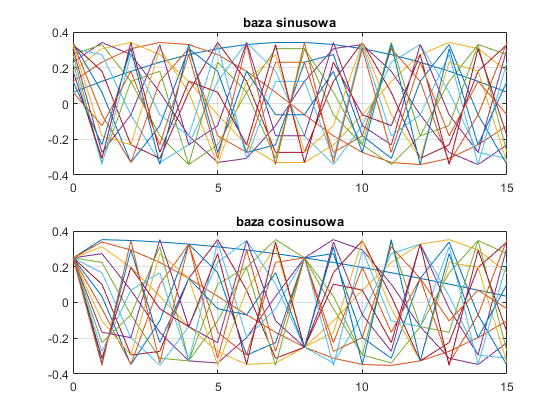


figure()
subplot(2,1,1); plot(n, real(baza_sin(:,:))); grid; title('baza sinusowa');
subplot(2,1,2); plot(n, real(baza_cos(:,:))); grid; title('baza cosinusowa');

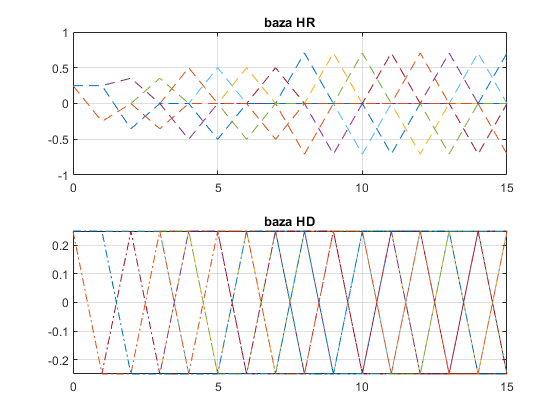

figure()
subplot(2,1,1); plot(n, real(baza_HR(:,:)),'--'); grid; title('baza HR');
subplot(2,1,2); plot(n, real(baza_HD(:,:)),'-.'); grid; title('baza HD');

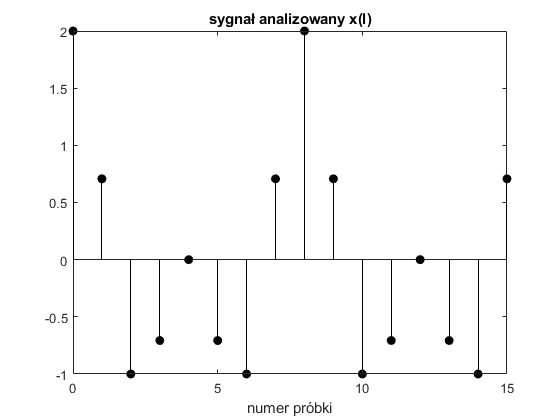

% Sprawdzenie ortonormalności wybranych funkcji bazowych
for k=1:N % zbudowanie macierzy transformacji
    Tf(k,1:N) = baza_fouriera(k,1:N); % transformacja Fouriera
    Tc(k,1:N) = baza_cos(k,1:N); % transformacja kosinusowa
    Ts(k,1:N) = baza_sin(k,1:N); % transformacja sinusowa
    THD(k,1:N) = baza_HD(k,1:N); % transformacja Hadamarda
    THR(k,1:N) = baza_HR(k,1:N); % transformacja Haara
end
T = Tc; % wybierz transformację
I = T * T'; % sprawdź, czy iloczyn jest macierzą diagonalną jednostkową

% Przykład analizy (dekompozycji) i syntezy sygnału
% Generacja sygnałów testowych
kk = 2; % testowy „indeks” częstotliwości, np. 1.35, 2, 2.5, 3
fi = 0; % przesunięcie fazowe 0, pi/8, pi/4, pi/2
n = 0 : N-1;
x1 = cos( (2*pi/N)*kk*n + fi ); % cz. rzeczywista bazy fourierowskiej
x2 = cos( pi*kk*(2*n+1)/NN + fi ); % wektor bazy kosinusowej
x3 = sin( pi*(kk+1)*(n+1)/(N+1) + fi ); % wektor bazy sinusowej
x4 = cos( (2*pi/N)*2*n + fi ) + cos( (2*pi/N)*4*n + fi );
x5 = [ ones(1,N/2) zeros(1,N/2) ];
x6 = [ -ones(1,N/4) ones(1,N/2) -ones(1,N/4) ];
x = x4; % wybór konkretnego sygnału do dekompozycji
T = THD; % wybór transformacji: Tf, Tc, Ts, THD, THR


a = T * x'; % analiza w zapisie macierzowym
y = T' * a; % synteza w zapisie macierzowym
y = y'; % zamień wektor pionowy na poziomy
figure()
stem(n,x,'filled','-k'); axis tight; title('sygnał analizowany x(l)');
xlabel('numer próbki');

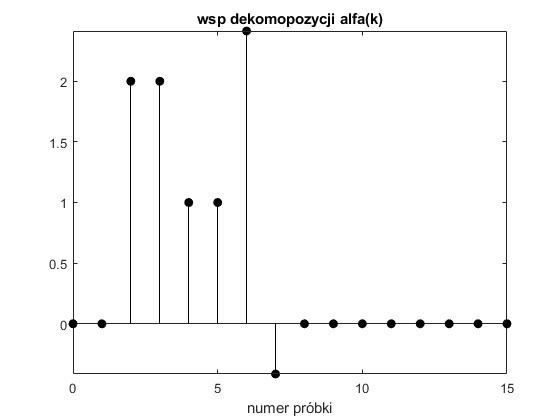

figure()
stem(n,real(a),'filled','-k'); axis tight; title('wsp dekomopozycji alfa(k)');
xlabel('numer próbki');

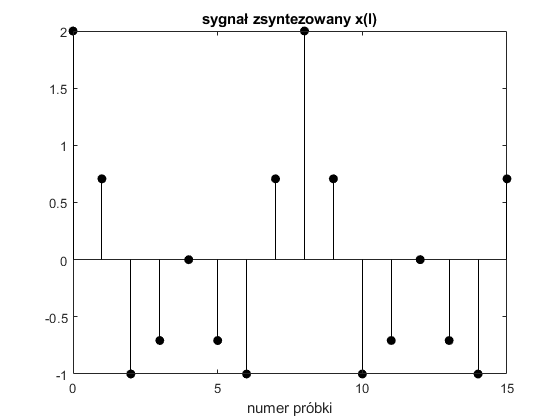

figure()
stem(n,y,'filled','-k'); axis tight; title('sygnał zsyntezowany x(l)');
xlabel('numer próbki');

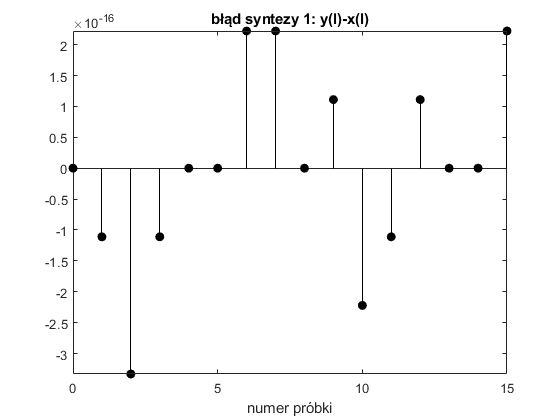

figure()
stem(n,y-x,'filled','-k'); axis tight; title('błąd syntezy 1: y(l)-x(l)');
xlabel('numer próbki');

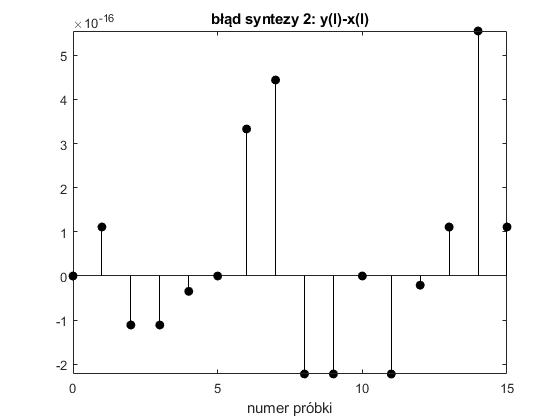


% Analiza i synteza w zapisie niemacierzowym
y=zeros(1,N); %
for k = 0 : N-1 % ANALIZA: oblicz współczynniki
    a(k+1) = sum( x .* conj(T(k+1,1:N)) ); %
end %
for k = 0 : N-1 % SYNTEZA: odtwórz sygnał
    y = y + a(k+1) * T(k+1,1:N); %
end %
figure()
stem(n,y-x,'filled','-k'); axis tight; title('błąd syntezy 2: y(l)-x(l)');
xlabel('numer próbki');